# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** : 박범섭**

**학번**** : 201715451**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 

x = [1,2,2,1];
N = 4;
X = dft(x, N);
magX = abs(X), phaX = angle(X)*180/pi

magX =     6.0000    1.4142    0.0000    1.4142


phaX =          0 -135.0000  -90.0000  135.0000


x = [1,2,2,1];
N = 4;
X = ifft(x, N);
magX = abs(X), phaX = angle(X)*180/pi

magX =     1.5000    0.3536         0    0.3536


phaX =      0   135     0  -135


2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.

x = [1, 2, 2, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0];
N = 16;
X = dft(x, N)

X =    6.0000 + 0.0000i   4.6447 - 3.1035i   1.7071 - 4.1213i  -0.5727 - 2.8793i  -1.0000 - 1.0000i  -0.2557 - 0.0509i   0.2929 - 0.1213i   0.1838 - 0.2750i   0.0000 + 0.0000i   0.1838 + 0.2750i   0.2929 + 0.1213i  -0.2557 + 0.0509i  -1.0000 + 1.0000i  -0.5727 + 2.8793i   1.7071 + 4.1213i   4.6447 + 3.1035i


magX = abs(X), phaX = angle(X)*180/pi

magX =     6.0000    5.5861    4.4609    2.9357    1.4142    0.2607    0.3170    0.3308    0.0000    0.3308    0.3170    0.2607    1.4142    2.9357    4.4609    5.5861


phaX =          0  -33.7500  -67.5000 -101.2500 -135.0000 -168.7500  -22.5000  -56.2500   90.0000   56.2500   22.5000  168.7500  135.0000  101.2500   67.5000   33.7500


2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$

xtilde1 = [4,1,-1,1]; 
N = 4;
Xtilde1 = dfs(xtilde1,N)

Xtilde1 =    5.0000 + 0.0000i   5.0000 + 0.0000i   1.0000 - 0.0000i   5.0000 + 0.0000i


2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$

xtilde2 = [2,0,0,0,-1,0,0,0];
N = 8;
Xtilde2 = dfs(xtilde2,N)

Xtilde2 =    1.0000 + 0.0000i   3.0000 + 0.0000i   1.0000 - 0.0000i   3.0000 + 0.0000i   1.0000 - 0.0000i   3.0000 + 0.0000i   1.0000 - 0.0000i   3.0000 + 0.0000i


3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\mathrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \mathrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 

n = 0:100;
xn = sinc((n-50)/2).^2;
N = length(xn); 
Xk = dft(xn,N); k = 0:N-1;
mag_Xk = abs(Xk);
pha_Xk = angle(Xk)*180/pi;
zei = find(mag_Xk < 0.00001);   
pha_Xk(zei) = zeros(1,length(zei));
subplot(2,1,1); H_s1 = stem(k,mag_Xk,'filled'); set(H_s1,'markersize',3); set(gca,'XTick',[0:20:N],'fontsize',8); axis([0,N,0,2.5])
set(gca,'YTick',[0:0.5:2.5],'fontsize',8); ylabel('Magnitude'); hold on
subplot(2,1,2); H_s2 = stem(k,pha_Xk,'filled'); set(H_s2,'markersize',3); set(gca,'XTick',[0:20:N],'fontsize',8); axis([0,N,-200,200])
set(gca,'YTick',[-180;-90;0;90;180],'fontsize',8); xlabel('k'); ylabel('Degrees');
hold on

2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

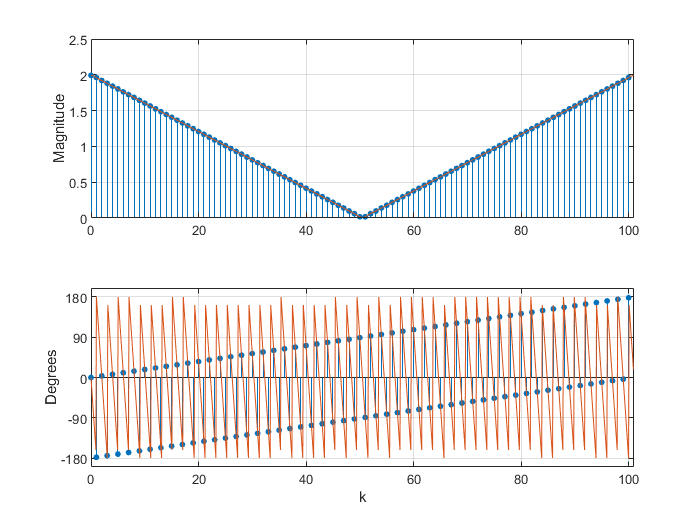

[X,w] = freqz(xn,1,1000,'whole');
mag_X = abs(X); pha_X = angle(X)*180/pi; 
Dw = (2*pi)/N;
subplot(2,1,1); plot(w/Dw,mag_X); grid
hold off
subplot(2,1,2); plot(w/Dw,pha_X); grid
hold off

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.

위 DFT는 X(e^jw)의 샘플링된 변형이 맞다.

4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.

재구성할 수 있다. 

$X\left(e^{j\omega } \right)$ = $\sum_{k=0}^{N-\;1} X\left(k\right)\phi \left(\omega -\frac{2\pi k}{N}\right)$ , $\phi \left(\omega \right)$=$e^{-j\frac{\omega \left(N-1\right)}{2}}$$\frac{\sin \left(\omega \frac{N}{2}\right)}{\textrm{Nsin}\left(\frac{\omega }{2}\right)}$

N=101일 때, $X\left(e^{j\omega } \right)$ = $\sum_{k=0}^{100} X\left(k\right)$=$e^{-\textrm{j50}\omega }$$\frac{\sin \left(\omega 50\ldotp 5\right)}{101\sin \left(\frac{\omega }{2}\right)}$    

function [Xk] = dfs(xn, N)
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ nk;
Xk = xn * WNnk;
end

function [Xk] = dft(xn, N)
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ nk;
Xk = xn * WNnk;
end